# **Численные методы в СПб АУ РАН**

## **Задание по практике №8**

Кузьмичев Артём, 4 курс

## **№2 (алгоритмы и программы к разделу 11.3)**

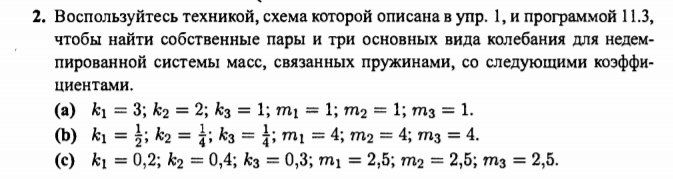

#### Решение

Рассмотрим недемпфированную систему масс, связанных пружинами

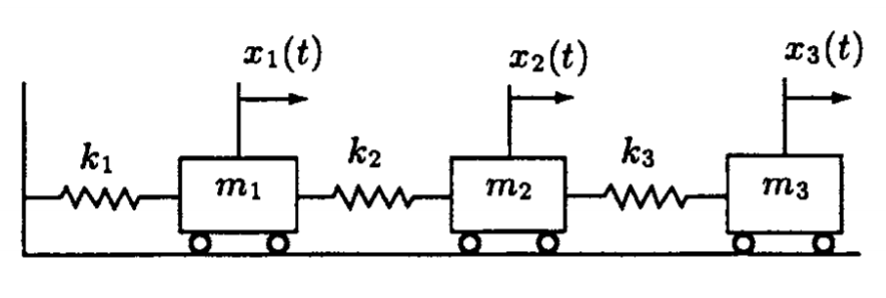

Воспользуемся законом Гука и запишем уравнения Ньютона для каждой из масс:


$${m_1 {{x_1 }^{\prime } }^{\prime } \left(t\right)=-k}_1 x_1 \left(t\right)+k_2 \left(x_2 \left(t\right)-x_1 \left(t\right)\right)$$



$$m_2 {{x_2 }^{\prime } }^{\prime } \left(t\right)=k_3 \left(x_3 \left(t\right)-x_2 \left(t\right)\right)-k_2 \left(x_2 \left(t\right)-x_1 \left(t\right)\right)$$



$${m_3 {{x_3 }^{\prime } }^{\prime } \left(t\right)=-k_3 }_3 \left(x_3 \left(t\right)-x_2 \left(t\right)\right)$$


Перепишем получившееся в следующем виде:


$$\left(k_1 +k_2 \right)x_1 \left(t\right)-k_2 x_2 \left(t\right)+m_1 {{x_1 }^{\prime } }^{\prime } \left(t\right)=0$$



$$-k_2 x_1 \left(t\right)+\left(k_2 +k_3 \right)x_2 \left(t\right)-k_3 x_1 \left(t\right)+m_2 {{x_2 }^{\prime } }^{\prime } \left(t\right)=0$$



$$-k_3 x_2 \left(t\right)+k_3 x_3 \left(t\right)+m_3 {{x_3 }^{\prime } }^{\prime } \left(t\right)=0$$


Видно, что можно переформулировать задачу в терминах матриц жёсткостей и масс:


$$\left\lbrack \begin{array}{ccc}
k_1 +k_2  & -k_2  & 0\\
-k_2  & k_2 +k_3  & -k_3 \\
0 & -k_3  & k_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)\\
x_3 \left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
m_1  & 0 & 0\\
0 & m_2  & 0\\
0 & 0 & m_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{{x_1 }^{\prime } }^{\prime } \left(t\right)\\
{{x_2 }^{\prime } }^{\prime } \left(t\right)\\
{{x_3 }^{\prime } }^{\prime } \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$$


Будем искать решения в виде гармонических колебаний: 


$$x_j \left(t\right)=s_j \sin \left(\omega t+\theta \right)$$
 


$$\left\lbrack \begin{array}{ccc}
k_1 +k_2  & -k_2  & 0\\
-k_2  & k_2 +k_3  & -k_3 \\
0 & -k_3  & k_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
s_1 \\
s_2 \\
s_3 
\end{array}\right\rbrack +\omega^2 \left\lbrack \begin{array}{ccc}
m_1  & 0 & 0\\
0 & m_2  & 0\\
0 & 0 & m_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
s_1 \\
s_2 \\
s_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
\frac{k_1 +k_2 }{m_1 } & \frac{-k_2 }{m_1 } & 0\\
\frac{-k_2 }{m_2 } & \frac{k_2 +k_3 }{m_2 } & \frac{-k_3 }{m_2 }\\
0 & \frac{-k_3 }{m_3 } & \frac{-k_3 }{m_3 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
s_1 \\
s_2 \\
s_3 
\end{array}\right\rbrack =\omega^2 \left\lbrack \begin{array}{c}
s_1 \\
s_2 \\
s_3 
\end{array}\right\rbrack$$


*Задача свелась к отысканию собственных пар матрицы, где собственный вектор отвечает за амплитуду данной моды колебаний, а собственное число - за соответствующую частоту *$\lambda_j ={\omega_j }^2$

*Воспользуемся для решения *

data_options = {'Пункт a', 'Пункт b','Пункт c', 'Ввести свои данные'};

choice = listdlg('ListString', data_options);

switch choice
    case 1
      k = [3,2,1];
      m = [1,1,1];
    case 2
      k = [0.5,0.25,0.25];
      m = [4,4,4];
    case 3
      kvec = [0.2,0.4,0.3];
      m = [2.5,2.5,2.5];
    case 4
      disp('Ввод данных задачи через консоль /n ...');
      kvec = [input('k1 = '),input('k2 = '),input('k3 = ')];
      m = [input('m1 = '),input('m2 = '),input('m3 = ')];
      disp('Данные приняты');
end

Введём симметричную матрицу, собственные значения которой мы ищем:$A=\left\lbrack \begin{array}{ccc}
\frac{k_1 +k_2 }{m_1 } & \frac{-k_2 }{m_1 } & 0\\
\frac{-k_2 }{m_2 } & \frac{k_2 +k_3 }{m_2 } & \frac{-k_3 }{m_2 }\\
0 & \frac{-k_3 }{m_3 } & \frac{-k_3 }{m_3 }
\end{array}\right\rbrack$

A = ...
[
    (k(1)+k(2))/m(1),    -k(2)/m(1)       ,      0       ;
    -k(2)/m(2)      ,   (k(2)+k(3))/m(2)  ,  -k(3)/m(2)  ;
    0               ,    -k(3)/m(3)       ,   k(3)/m(3)  ;
];

С помощью функции jacobi (опредление в конце скрипта .mlx) получим диагонализованную матрицу A и матрицу из собственных векторов;

epsilon = 0.00001;
[V,D] = jacobi(A, epsilon)

V =     0.7887    0.5774    0.2113
   -0.5774    0.5774    0.5774
    0.2113   -0.5774    0.7887


D =     0.2333         0         0
         0    0.1250         0
         0         0    0.0167


Найдём собственные значения и вектора, используя eig pb matlab и оценим разницу:

[Veig,Deig] = eig(A)

Veig =     0.2113   -0.5774   -0.7887
    0.5774   -0.5774    0.5774
    0.7887    0.5774   -0.2113


Deig =     0.0167         0         0
         0    0.1250         0
         0         0    0.2333


*Видно, что результаты алгоритма Якоби и eig(A) одинаковы с точностью до перестановки собственных чисел и перестановки+домножения на число собственных векторов*

Сформулируем ответ на задачу о колебаниях нескольких тел с помощью равенства $\omega_i =\sqrt{\lambda_i }$

**Собственные циклические частоты системы:**

omega = sqrt(diag(D));
fprintf([' \n ω1 = %f \t ω2 = %f \t ω3 = %f '], omega)

 
 ω1 = 0.482963 	 ω2 = 0.353553 	 ω3 = 0.129410 

**Колебательные моды системы:**

V

V =     0.7887    0.5774    0.2113
   -0.5774    0.5774    0.5774
    0.2113   -0.5774    0.7887


## Приложение

#### Определение функции, осуществляющей метод Якоби

function [V,D]=jacobi(A,epsilon)
%Вход   -   A - матрица n x n
%       -   epsilon - допустимое значение
%Выход  -   V - матрица собственных векторов размера n x n (матрица перехода в собственный базис)
%                   
%       -   D - диагонализованная матрица A

D=A;
[~,n] = size(A);
V =eye(n);

% Вычисление строки p и столбца q наибольшего по абсолютной величине элемента матрицы A, не лежащего на диагонали
[p, q] = maxIndices(D);

while 1
    %Вычисление ортогональной матрицы вращения R
    t=D(p,q)/(D(q,q)-D(p,p));
    c=1/sqrt(t^2+1);
    s=c*t;
    R=[c, s;-s, c];
    
    %Обнуление Dpq и Dqp с помощью R
    D([p, q],:)=R'*D([p, q],:);
    D(:,[p, q])=D(:,[p, q])*R;
    V(:,[p,q])=V(:,[p,q])*R;
    
    %Новые максимальные индекмы
    [p, q] = maxIndices(D);
    
    if (abs(D(p,q))<epsilon*sqrt(sum(diag(D).^2)/n)) 
        % Условие выхода из цикла - модуль максимального недиагонального элемента в матрице
        %  более чем в epsilon раз меньше евклидовой нормы диагональных элементов
     
        D=diag(diag(D));    % отбрасываем всё недиагональное
        break
    end  
end
end

Определение функции, осуществляющей вычисление строки p и столбца q 

наибольшего по абсолютной величине элемента матрицы A, не лежащего на диагонали

function [p, q] = maxIndices(D)
    [z,p]=max(abs(D-diag(diag(D)))); % diag(diag()) - это способ сделать диагональную матрицу, состояющую из диагональных элементов исходной матрицы, 
    [~,q]=max(z);
    p = p(q);
end